## BCI Competition 2008 – Graz data set A

This data set consists of EEG data from 9 subjects. The cue-based BCI paradigm consisted of four different motor imagery tasks, namely the imagination of movement of the left hand (class 1), right hand (class 2), both feet (class 3), and tongue (class 4). Two sessions on different days were recorded for each subject. Each session is comprised of 6 runs separated by short breaks. One run consists of 48 trials (12 for each of the four possible classes), yielding a total of 288 trials per session.

## Load Data

Twenty-two Ag/AgCl electrodes (with inter-electrode distances of 3.5 cm) were used to record the EEG; the montage is shown in Figure 3 left. All signals were recorded monopolarly with the left mastoid serving as reference and the right mastoid as ground. The signals were sampled with 250 Hz and bandpass-filtered between 0.5 Hz and 100 Hz. The sensitivity of the amplifier was set to 100 µV. An additional 50 Hz notch filter was enabled to suppress line noise.

mat = dir('./data/*.mat');
for K = 1 : length(mat)
  thisfile = mat(K).name;
  thisdata = load(strcat('./data/',thisfile));
end

## Plot a subject trial signals 

data{1,6}

ans =             X: [96735x25 double]
        trial: [48x1 double]
            y: [48x1 double]
           fs: 250
      classes: {'left hand'  'right hand'  'feet'  'tongue'}
    artifacts: [48x1 logical]
       gender: 'female'
          age: 24


So we have for each subject a train and evaluation dataset. We will start by analyzing the evaluation dataset that contains 8 attributes. The X attributes contains the 25 channels signals values (22 EEG and 3 EOG) samplified with a rate of 250 Hz and bandpass-filtered between 0.5 Hz and 100 Hz. The trial vector contains run index and the y vector contains the target value with subject informations.

data{1,6}.X

ans =    -9.3750   -6.2500   -5.7129   -5.0293   -6.6406   -7.8125   -7.9590   -4.3945   -2.1973   -2.0020   -5.0293   -5.3223   -5.2734   -0.6348   -2.6855    0.1465   -4.5898   -6.4453   -0.3418   -1.4648   -2.1973    0.5371    2.4414  -12.2070   -3.9062
   70.1660   77.4902   74.0723   75.5371   72.0215   73.7793   81.3965   79.4922   78.6621   79.3457   75.4395   78.8574   82.1289   83.0566   77.6855   80.5176   76.7578   77.7344   80.0293   80.0293   77.8809   78.9551   85.4492   62.5000   73.7305
   39.7949   47.7539   44.6289   40.0879   40.9668   40.2344   70.6543   52.3926   48.3887   43.5547   44.9707   43.5059   48.9258   53.6621   50.0977   44.3848   46.5820   49.2188   50.7324   47.7051   46.3379   44.0918   46.8750   27.3438   44.9219
   33.4473   38.2812   36.9629   36.7676   34.8633   36.3770   42.7734   41.2109   40.9180   41.8457   40.2344   39.6973   34.6680   46.3867   45.1172   45.3125   44.5312   43.9941   53.7598   47.2168   46.3867   47.2168   44.9219   27.3438 

data{1,6}.trial

ans =          251
        2254
        4172
        6124
        8132
       10243
       12160
       14210
       16141
       18139


eeg_signal=data{1,6}

eeg_signal =             X: [96735x25 double]
        trial: [48x1 double]
            y: [48x1 double]
           fs: 250
      classes: {'left hand'  'right hand'  'feet'  'tongue'}
    artifacts: [48x1 logical]
       gender: 'female'
          age: 24


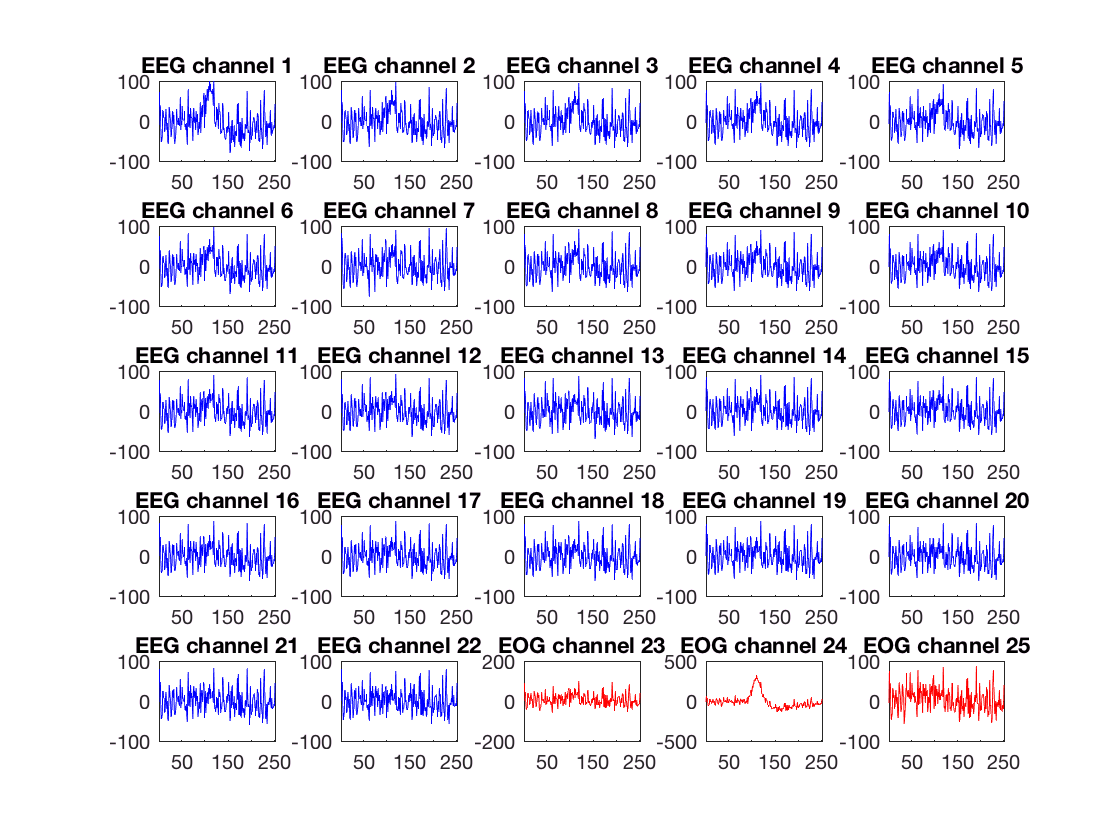

figure
for k=1:25
    signal_type='EEG';
    color='blue';
    if k>22
        signal_type = 'EOG';
        color='red';
    end
    subplot(5,5,k);
    plot([1:251],data{1,6}.X(1:251,k:k),color);
    xlim([1 251]);
    title(sprintf('%s channel %s',signal_type,int2str(k)));
end

We plot differents channels signals for a signal trial for a specific subject. We used the function plot_signal( data, subject,trial_start, trial_end ) to do that. 

## Generate Common Spatial Pattern (CSP)

Motor imagery is a mental process of a motor action. It includes preparation for movement, passive observations of action and mental operations of motor representations implicitly to explicitly. The ability of an individual to control his EEG through imaginary mental tasks enables him to control device through brain computer interface (BCI). 

EEG signals are formalized as : $\Big\{ E_n \Big\}_{n=1}^N  \in R^{channel \times time}$, $N = 9 \times 48 = 432$is the number of trials, $channel = 22 $ EEG channels, $time = 250 \times 3 = 750$ is the range of time domain. We used 2.5 s for fixation cross and 1.5 s for cue and 3s with a rate of 250 Hz for motor imagery.

We have to transform each EEG signal to feature vector $E_n \in R^{channel \times time} \longrightarrow x_n \in R^{d}$ where $d$is the number of features for each channel, so we will have $d \times channel$ feature for each subject.

The CSP filters is an effective method of feature extraction for EEG motor imagery classification, it's the most popular algorithm in BCI field for learning spatial filters for oscillatory processes

subjects = [4:9];
[line,nb_subject] = size(subjects);
[nb_trials,column] = size(data{1,5}.trial);
targets = [];
[nb_observations,nb_channels] = size(data{1,5}.X);
features_vectors = zeros(nb_trials*nb_subject,nb_channels);

for s=1:nb_subject
    for k=2:nb_trials
        start_index = data{1,subjects(s)}.trial(k-1);
        end_index = data{1,subjects(s)}.trial(k);
        mean_array = data{1,subjects(s)}.X(start_index:end_index,:);
        features_vectors(k,:)=mean(mean_array);
    end
    targets = [targets;data{1,subjects(s)}.y];
end
features_vectors(:,end)=targets;
features_vectors(:,end)

ans =      1
     2
     2
     1
     2
     1
     2
     3
     2
     4


%ind = features_vectors(:,end) == 1;
%A1 = features_vectors(ind,:)
%features_vectors(:,end)
targets

targets =      1
     2
     2
     1
     2
     1
     2
     3
     2
     4


%figure
%plot([1:12],A1(:,1))